# Module 8: Localization clustering

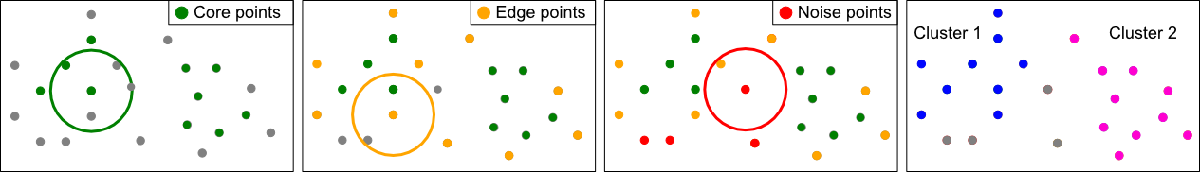

In many cases, multiple localizations belong together to an underlying structure or cluster. To investigate this, localizations can be clustered together, and these clusters can be investigated. In this module, we showcase one way of clustering: DBSCAN.

## Variable initialisation

% Loading data
data = commonFunctions.readTXTRapidSTORM('Data\RNAP_E_coli_1_cell.txt');

%Initialising two variables for distance to search in (eps), and minimum
%number of neighbours (minPts)
eps = 50;
minPts = 20;

% For easier understanding, we will treat this data as a table in matlab,
% so we can have headers and select on those
frame = data(:,1);
x = data(:,2);
y = data(:,3);
intensity = data(:,4);
data = table(frame,x,y,intensity);

%Additionally, we add columns for core, cluster, and label,
core = zeros(size(frame));
cluster = zeros(size(core));
label = zeros(size(core));
data = addvars(data,core,cluster,label);

## Nearest neighbour finding

To perform DBSCAN, we must know what the nearest neighbours are within a specific radius (eps). The number of nearest neighbours is used to determine whether every localization is a core, cluster, or noise point.

% Next, we find neighbours in the localizations and add it to the data table
neighbours = rangesearch([data.x data.y],[data.x data.y],eps);
% We calculate the number of neighbours
% and add both the neighbour IDs and the number of neighbours to the table
n_neigh = zeros(size(core));
for i = 1:size(neighbours)
    n_neigh(i) = size(neighbours{i},2);
end
data = addvars(data,neighbours,n_neigh);

## Core point determination

Every localization that has enough neighbours is set to be a core, and also a cluster (i.e. every core point is also a cluster core, not every cluster point is a core point).

% Now we assign core and cluster boolean operators.
% We make sure that everything above-equal the minimum nr of neighbours is
% a core and a cluster, and everything below is not.
filt = (data.n_neigh >= minPts);
data.core(filt) = 1;
data.cluster(filt) = 1;
filt = (data.n_neigh < minPts);
data.core(filt) = 0;
data.cluster(filt) = 0;

## Cluster point determination

Ever point that's not a core point, but that does have at least 1 core neighbour, will be a cluster point. We apply that logic here.

All points that are neither cluster nor core after this code are noise points.

% Next, every non-core point that has a neighbour that is core, should
% become a cluster
filt_noncore = (data.core == 0);
for i = 1:size(filt_noncore,1)
    if filt_noncore(i)
        % We check the core-ness of every neighbour in the 'neighbours'
        % column
        if sum(data.core(cell2mat(data.neighbours(i)))) > 0
            data.cluster(i) = 1;
        end
    end
end

## Label assigning

Now that it's known which points are core and cluster, these should be given labels.

For this, we create a recursion system. Basically, we loop over every localization, and if it's core or cluster and does not yet have a label, we assign the current label ID. If it is a core point (i.e. not a cluster poin), we loop over all it's neighbours, and repeat this logic. This recursion ensures that every localization has their correct label assigned. We have a function below that we use for this: givePointAndNeighboursCurrentID on line 70 (hyperlink).

%We start with a current label ID of 1
curlabelid = 1;

%And we loop over all data points
for index = 1:size(data,1)
    %And if it's a core point and does not yet have a label
    if data.core(index) && data.label(index) == 0
        %We start the recursive function
        data=givePointAndNeighboursCurrentID(data,index, curlabelid);
        %After the recursive function is done, this cluster is fully defined,
        %so we increase the label ID.
        curlabelid=curlabelid+1;
    end
end

## Cluster visualisation

Now we can visualise the localizations, based on their label ID. This clearly shows multiple clusters present.

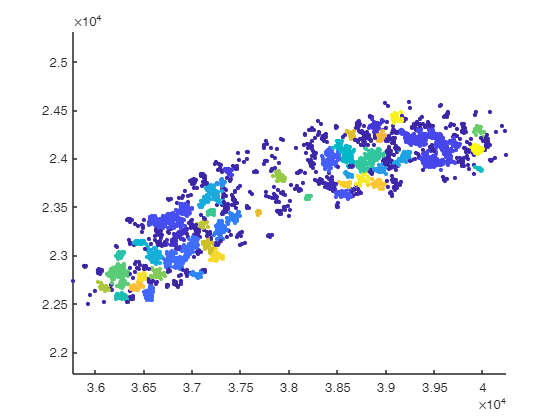

%And we show the figure
figure()
scatter(data.x,data.y,10,data.label,'filled')
axis equal

## Function declaration

function data=givePointAndNeighboursCurrentID(data,index, curlabelid)
    %First, we give this point the current label
    data.label(index) = curlabelid;
    %Next, we find all the neighbours and store them in an array
    neighbourarr = cell2mat(data.neighbours(index));
    %Then we loop over all their neighbours
    for n = 1:data.n_neigh(index)
        neighid = neighbourarr(n);
        %And we check if all the neighbours do not yet have a label, and are a
        %cluster point
        if data.label(neighid) == 0 && data.cluster(neighid) == 1
            %If this is the case, it will be give the same label
            data.label(neighid) = curlabelid;
            if data.core(neighid)
                %If it's also a core, it will perform this same function (i.e.
                %recursive), and it will look at all its neighbours and be
                %given the same label ID as currently is being assigned.
                data=givePointAndNeighboursCurrentID(data,neighid,curlabelid);
            end
        end
    end
end